## 曲线拟合

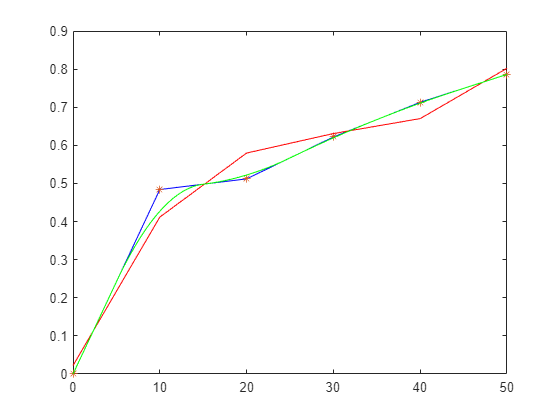

clf;clc;clear
% a = 1:1:6;  %横坐标
% b = [8.0 9.0 10.0 15.0 35.0 40.0]; %纵坐标
a = [0 10 20 30 40 50];
b = [0 0.484 0.512 0.622 0.713 0.786];
plot(a, b, 'b');  %自然状态的画图效果
hold on
plot(a, b, '*');  %将每个点 用*画出来
%% 第一种，画平滑曲线的方法
c = polyfit(a, b, 3);  %进行拟合，c为3次拟合后的系数
d = polyval(c, a, 1);  %拟合后，每一个横坐标对应的值即为d
plot(a, d, 'r');  %拟合后的曲线
%% 第二种，画平滑曲线的方法
values = spcrv([[a(1) a a(end)];[b(1) b b(end)]],3);
plot(values(1,:),values(2,:), 'g');
hold off

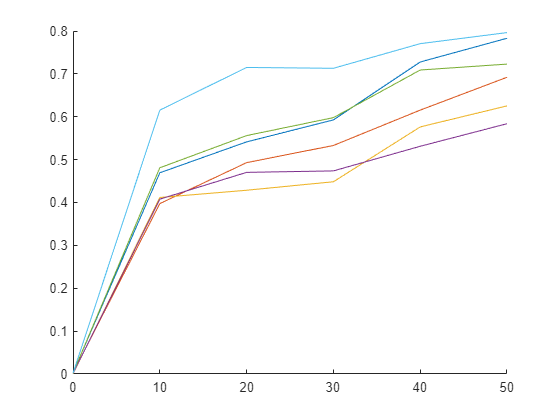

clf;clc;clear
a = zeros(12,6);
b = zeros(12,6);
%%
a(1:6,:) = [0 10 20 30 40 50;
    0 10 20 30 40 50;
    0 10 20 30 40 50;
    0 10 20 30 40 50;
    0 10 20 30 40 50;
    0 10 20 30 40 50;];
b(1,:) = [0 0.484 0.512 0.622 0.713 0.786];
b(2,:) = [0 0.412 0.464 0.562 0.601 0.695];
b(3,:) = [0 0.415 0.422 0.455 0.573 0.626];
b(4,:) = [0 0.414 0.458 0.486 0.525 0.585];
b(5,:) = [0 0.492 0.534 0.620 0.698 0.725];
b(6,:) = [0 0.624 0.698 0.730 0.762 0.798];

a(7:12,:) = [0 0.2 0.4 0.6 0.8 1;
    0 0.2 0.4 0.6 0.8 1;
    0 0.2 0.4 0.6 0.8 1;
    0 0.2 0.4 0.6 0.8 1;
    0 0.2 0.4 0.6 0.8 1;
    0 0.2 0.4 0.6 0.8 1;];
b(7,:) = [0.78 0.71 0.63 0.46 0.25 0];
b(8,:) = [0.72 0.68 0.50 0.45 0.26 0];
b(9,:) = [0.76 0.65 0.52 0.43 0.16 0];
b(10,:) = [0.68 0.65 0.48 0.35 0.17 0];
b(11,:) = [0.79 0.73 0.65 0.48 0.23 0];
b(12,:) = [0.75 0.72 0.68 0.62 0.28 0];
figure
% plot(a, b, 'b');  %自然状态的画图效果
hold on;
%% 第一种，画平滑曲线的方法
for i=1:6
    c = polyfit(a(i,:), b(i,:), 4);  %进行拟合，c为4次拟合后的系数
    d = polyval(c, a(i,:), 1);  %拟合后，每一个横坐标对应的值即为d
    plot(a(i,:), d);  %拟合后的曲线
    hold on
end
% plot(a, b, '*');  %将每个点 用*画出来
hold off;

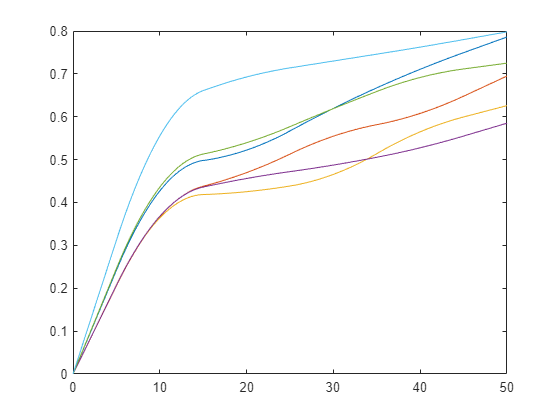

%% 第二种，画平滑曲线的方法
figure;
for i = 1:6
    values = spcrv([[a(i,1) a(i,:) a(i,end)];[b(i,1) b(i,:) b(i,end)]],3);
    plot(values(1,:),values(2,:));
    hold on
end
hold off

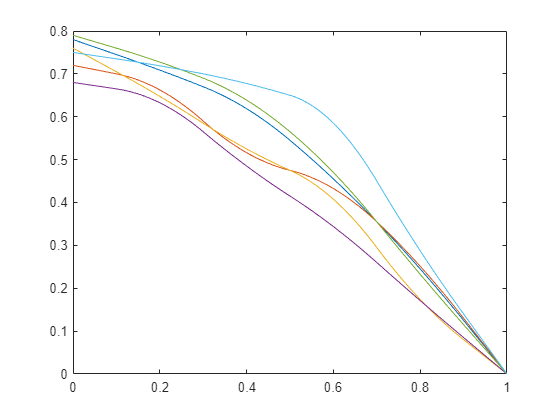

figure;
for i = 7:12
    values = spcrv([[a(i,1) a(i,:) a(i,end)];[b(i,1) b(i,:) b(i,end)]],3);
    plot(values(1,:),values(2,:));
    hold on
end
hold off

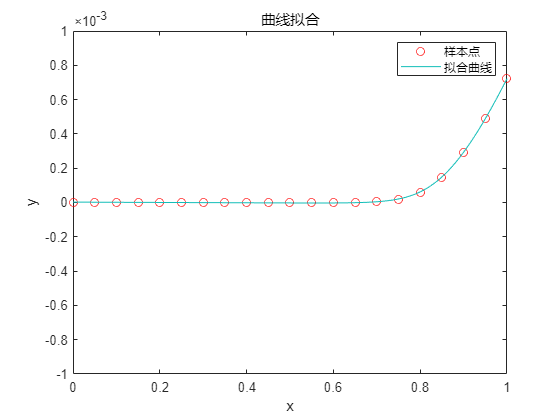

clear;clc;clf
F=@(p,x)p(1)*exp((x(:,1)-x(:,2)*p(4))/0.026/p(6))+p(2)*exp((x(:,1)-x(:,2)*p(4))/0.026/p(7))+(x(:,1)-x(:,2)*p(4))/p(5)-p(1)-p(2)+p(3)-x(:,2); 
x=[0,4.84827E-9 
0.05,7.20861E-9 
0.1,9.486E-9 
0.15,1.33346E-8 
0.2,1.85467E-8 
0.25,2.54804E-8 
0.3,3.57885E-8 
0.35,4.94846E-8 
0.4,6.86021E-8 
0.45,9.34068E-8 
0.5,1.36416E-7 
0.55,2.18504E-7 
0.6,4.51033E-7 
0.65,1.2785E-6 
0.7,4.57114E-6 
0.75,1.70904E-5 
0.8,5.62476E-5 
0.85,1.45646E-4 
0.9,2.93975E-4 
0.95,4.91251E-4 
1,7.21464E-4 ]; 
p0=[3 5 4 10 9 10 4];%%因为你这个函数很变态，初值选择不好得不到好结果，这个初值不错 
warning off 
p=nlinfit(x,zeros(size(x,1),1),F,p0); 
% disp('I1、I2、IL、Rs、Rsh、n1、n2分别为：'); 
% disp(num2str(p)); 
plot(x(:,1),x(:,2),'ro');hold on; 
ezplot(@(x,y)F(p,[x,y]),[0,1,-1e-3,1e-3]); 
title('曲线拟合');legend('样本点','拟合曲线')

## 直线

根据直线通式（**y=b*x+c**）求出通过两定点的直线的参数(b,c)

clf;clc;clear
syms b c x1 x2 y1 y2 %定义符号变量
ex1 = b*x1+c-y1;
ex2 = b*x2+c-y2;
[b,c] = solve(ex1,ex2,b,c);%用来求解线性方程组的解析解或者精确解
% 求出直线方程
A = [1.22 2];
B = [5 6];
x1 = A(1); x2 = B(1);
y1 = A(2); y2 = B(2);
b = subs(b)%符号计算函数，表示将符号表达式中的某些符号变量替换为指定的新的变量

$$b = \frac{200}{189}$$

c = subs(c)

$$c = \frac{134}{189}$$

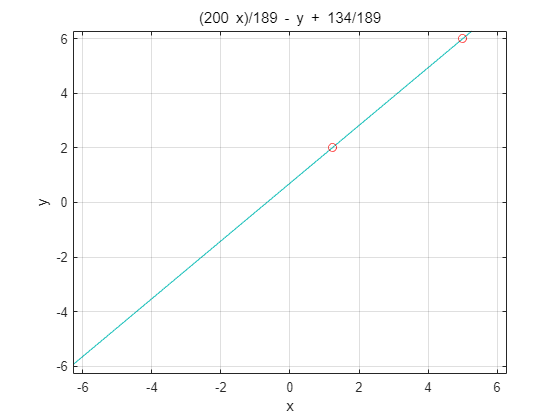

% 作图验证
syms x y
ezplot(b*x+c-y);%绘制符号函数的图像,只需给出函数的解析表达式即可,不需计算,
hold on
plot(x1,y1,'ro');
plot(x2,y2,'ro');
grid on
hold off

## 计算两条线的交点及三角形垂心

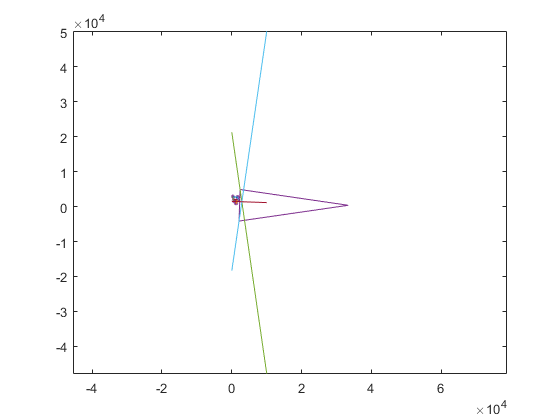

% 为了让整个流程比较完整，
% 1、我用了12个点，每两个点一条线，能组成6条线；
% 2、每两条线相交于一点，一共有3个点；
% 3、3个点构成了三角形的三个顶点，然后再根据三个顶点计算三角形的垂心。

X = [294.94, 668.61, 1678.70, 1731.25, 540.16, 1731.25, 335.80, 1696.22, 1106.51, 1404.28, 1351.74, 1591.12];  
Y = [2959.12, 1464.42, 2848.19, 1914.00, 1978.22, 1919.83, 2778.12, 2678.86, 892.23, 1832.25, 880.56, 1820.58];
plot(X, Y, '.');

for i = 1: 6
    plot([X(2*i-1), X(2*i)], [Y(2*i-1), Y(2*i)]);
    hold on;
end
%全部直线的方程式
a = zeros(6, 1);
b = zeros(6, 1);
for i = 1: 6
    a(i, 1) = (Y(2*i) - Y(2*i-1)) / (X(2*i) - X(2*i-1));
    b(i, 1) = Y(2*i) - a(i, 1) * X(2*i);
end
%两两之间的交点
     points = zeros(3, 2);
for i = 1: 3
    % 两个直线方程之差的函数
    fun = @(x) (a(2*i-1, 1) * x + b(2*i-1, 1)) - (a(2*i, 1) * x + b(2*i, 1));
    
    % 两个直线方程之差函数值为0时的x值，由得到的x值计算y值
    points(i, 1) = fzero(fun, 2);
    points(i, 2) = a(2*i) * points(i, 1) + b(2*i, 1);
end

hold on;
plot([points(:, 1); points(1, 1)], [points(:, 2); points(1, 2)])

% 计算各个顶点连线的方程式
slope1_2 = (points(2, 2) - points(1, 2)) / (points(2, 1) - points(1, 1));
slope2_3 = (points(3, 2) - points(2, 2)) / (points(3, 1) - points(2, 1));
slope1_3 = (points(3, 2) - points(1, 2)) / (points(3, 1) - points(1, 1));
b1_2 = points(2, 2) - slope1_2 * points(2, 1);
b2_3 = points(3, 2) - slope2_3 * points(3, 1);
b1_3 = points(1, 2) - slope1_3 * points(1, 1);
slopevertical1_2 = -1 / slope1_2;
slopevertical2_3 = -1 / slope2_3;
slopevertical1_3 = -1 / slope1_3;

verticalb1_2 = points(3, 2) - slopevertical1_2 * points(3, 1);
verticalb2_3 = points(1, 2) - slopevertical2_3 * points(1, 1);
verticalb1_3 = points(2, 2) - slopevertical1_3 * points(2, 1);

% 设置预绘制直线的两个端点的X值
verticalLinePoints = zeros(6, 2);
for i = 1: 3
    verticalLinePoints(2*i-1, 1) = 0;
    verticalLinePoints(2*i, 1) = 10000;
    if i == 1
         slopevertical = slopevertical1_2;
         verticalb = verticalb1_2;
    elseif i == 2
         slopevertical = slopevertical2_3;
         verticalb = verticalb2_3;
    else
	 slopevertical = slopevertical1_3;
	 verticalb = verticalb1_3;
    end
    
   % 计算两个端点的y值
    verticalLinePoints(2*i-1, 2) = slopevertical * verticalLinePoints(2*i-1, 1) + verticalb;
    verticalLinePoints(2*i, 2) = slopevertical * verticalLinePoints(2*i, 1) + verticalb;
end

hold on;	% 为了保留前面绘制的图像，使用hold on
plot(verticalLinePoints(1:2, 1), verticalLinePoints(1:2, 2));
plot(verticalLinePoints(3:4, 1), verticalLinePoints(3:4, 2));
plot(verticalLinePoints(5:6, 1), verticalLinePoints(5:6, 2));
axis equal;%axis square/将当前坐标系图形设置为方形  axis equal/将横轴纵轴的定标系数设成相同值

## 线条及标记

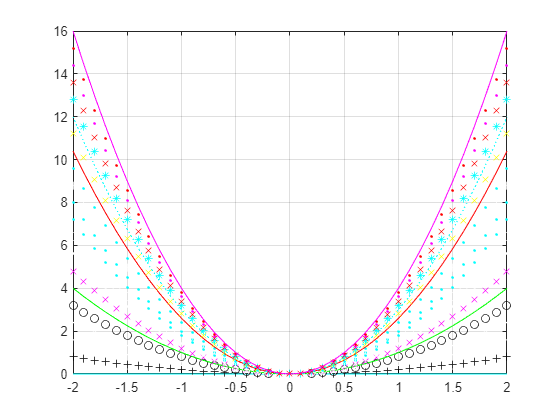

clf;clc;clear
x=-2:0.1:2;
coArray=['y','m','c','r','g','b','w','k'];%初始颜色数组
liArray=['o','x','+','*','-',':','-.','--','.'];%初始线条数组
for i=0:0.2:4
    y=i*x.^2;
    liPos=randi([1,length(liArray)],1,1);%随机选取线条
    liVal=liArray(liPos);%取得随机线条
    coPos=randi([1,length(coArray)],1,1);%随机选取颜色
    coVal=coArray(coPos);%取得随机颜色
    plot(x,y,[coVal liVal]);
    hold on;
end
grid;
hold off

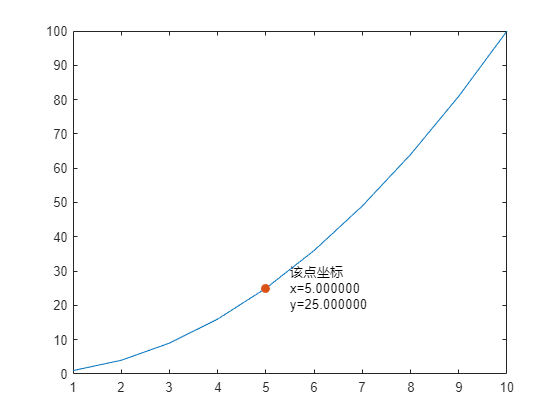

% 线条标记组合
clf;clc;clear
t = 0:pi/20:2*pi;
figure
plot(t,sin(t),'-.r*')
hold on
plot(t,sin(t-pi/2),'--mo')
plot(t,sin(t-pi),':bs')
hold off
%%  打印标记
clf;clc;clear
x=1:10;
y=x.^2;
figure
plot(x,y);
hold on
str=sprintf('该点坐标\nx=%f\ny=%f',5,25);
plot(5,25,'marker','.','markersize',20)
text(5.5,25,str);
hold off

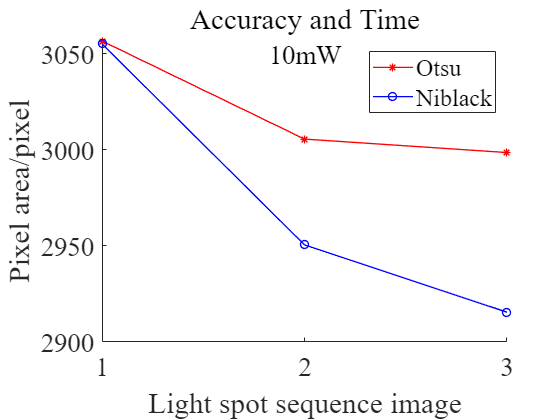

clf;clc;clear
x = 1:3;
y1 = [3213	3111	3097];
y2 = [3210	3001	2931];
figure
hold on
plot(x,y1,'r-*','LineWidth',1)
plot(x,y2,'b-o','LineWidth',1)

set(gca,'xtick',0:1:3)
set(gca,'yticklabel',get(gca,'ytick'))
set(get(gca,'XLabel'),'FontSize',20,'FontName','Times New Roman');%设置X坐标标题字体大小，字型  
set(get(gca,'YLabel'),'FontSize',20,'FontName','Times New Roman');%设置Y坐标标题字体大小，字型  
set(gca,'FontName','Times New Roman','FontSize',20)%设置坐标轴字体大小，字型  
text(2,max(get(gca,'ytick')),'10mW','horiz','center','FontSize',20,'FontName','Times New Roman'); %设置文本字型字号  

legend({'Otsu';'Niblack'});
xlabel('Light spot sequence image');
ylabel('Pixel area/pixel');
title('Accuracy and Time');


% x = [x1 y1];
% y = [x2 y2];
% X = [x1 x2];
% Y = [y1 y2];
% % axis([0 225 0 225]);
% line(X,Y,'color','y','LineWidth','1');
% line属性
% Color:线条颜色  'color',[rand rand rand]随机色
% LineStyle: 线型
% LineWidth: 线宽
% Marker: 点型
% MarkerSize: 点的大小
% MarkerFaceColor: 点的内部颜色。

## 填充

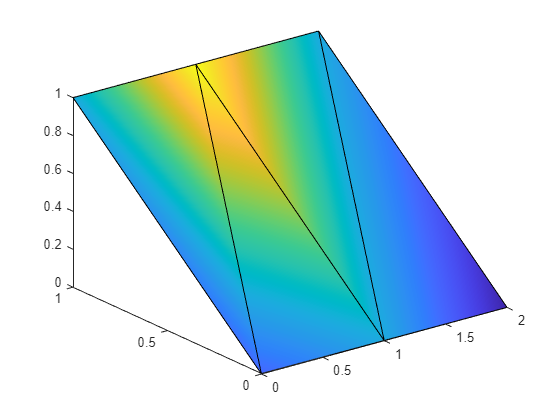

clf;clc;clear
X = [0 1 1 2; 1 1 2 2; 0 0 1 1];
Y = [1 1 1 1; 1 0 1 0; 0 0 0 0];
Z = [1 1 1 1; 1 0 1 0; 0 0 0 0];
C = [0.5000 1.0000 1.0000 0.5000;
     1.0000 0.5000 0.5000 0.1667;
     0.3330 0.3330 0.5000 0.5000];
figure('name','三维多边形')
% fill3(X,Y,Z,C) 填充三维多边形。X、Y 和 Z 三元组指定多边形顶点。
% 如果 X、Y 或 Z 为矩阵，则 fill3 会创建 n 个多边形，其中 n 为矩阵中的列数。
% fill3 必要时可将最后一个顶点与第一个顶点相连以闭合这些多边形。
% X、Y 和 Z 的值可以是数值、日期时间、持续时间或类别值。
% C 指定颜色，其中 C 为当前颜色图索引的向量或矩阵。
% 如果 C 为行向量，length(C) 必须等于 size(X,2) 和 size(Y,2)；如果 C 为列向量，length(C) 必须等于 size(X,1) 和 size(Y,1)。
fill3(X,Y,Z,C)

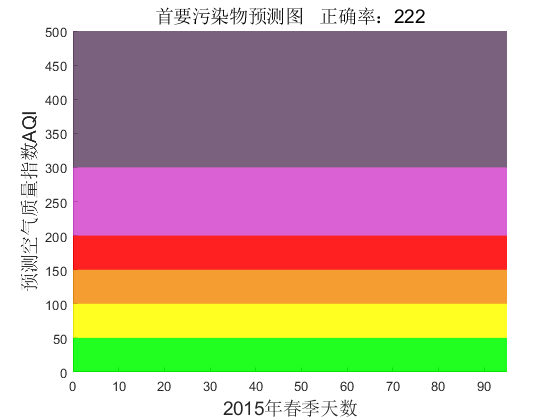

clf;clc;clear
figure
hold on
fill([0 95 95 0],[0 0 50 50],'g','edgecolor','none','facealpha',0.87)%edgecolor边沿颜色 facealpha透明度
fill([0 95 95 0],[50 50 100 100],'y','edgecolor','none','facealpha',0.87)
fill([0 95 95 0],[100 100 150 150],[243/255,143/255,17/255],'edgecolor','none','facealpha',0.87)
fill([0 95 95 0],[150 150 200 200],'r','edgecolor','none','facealpha',0.87)
fill([0 95 95 0],[200 200 300 300],[211/255,73/255,206/255],'edgecolor','none','facealpha',0.87)
fill([0 95 95 0],[300 300 500 500],[102/255,73/255,107/255],'edgecolor','none','facealpha',0.87)
xlabel('2015年春季天数','FontSize',14);
ylabel('预测空气质量指数AQI','FontSize',14);

string = {['首要污染物预测图   ',['正确率：',num2str(222)]]};
title(string,'FontSize',14)
axis([0 95 0 500]);%axis([xmin,xmax,ymin,ymax])
xlim([0 95]);%只限x

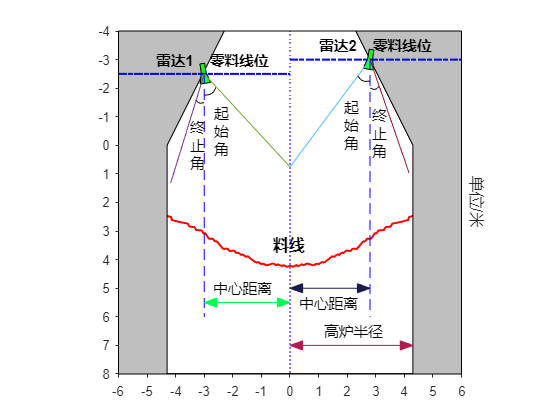

clf;clc;clear
% fill3(X,Y,Z,C) 填充三维多边形。X、Y 和 Z 三元组指定多边形顶点。
% 如果 X、Y 或 Z 为矩阵，则 fill3 会创建 n 个多边形，其中 n 为矩阵中的列数。
% fill3 必要时可将最后一个顶点与第一个顶点相连以闭合这些多边形。
% X、Y 和 Z 的值可以是数值、日期时间、持续时间或类别值。
% C 指定颜色，其中 C 为当前颜色图索引的向量或矩阵。
% 如果 C 为行向量，length(C) 必须等于 size(X,2) 和 size(Y,2)；如果 C 为列向量，length(C) 必须等于 size(X,1) 和 size(Y,1)。 
% fill3([0 10 95 3 0],[0 10 0 50 50],[1 1 1 1 1],'g','edgecolor','none','facealpha',0.87)%edgecolor边沿颜色 facealpha透明度
% clc;close all;clear
figure
hold on
plot([-4.39892857881150,-4.34037537210788,-4.28159208266542,-4.22258695556051,-4.16336826698498,-4.12857492524466,-4.06790808088155,-4.00704937065465,-3.94600733074352,-3.88479052304196,-3.82340753395710,-3.76186697320502,-3.70017747260319,-3.63834768485969,-3.57638628235961,-3.52834164484428,-3.46507071395038,-3.40169247251754,-3.33821581012042,-3.28438945437809,-3.21966391373594,-3.15486548386454,-3.09000325353740,-3.03050442581810,-2.96445918657912,-2.90162893326872,-2.83660330902180,-2.76830644491869,-2.70000000000000,-2.63060932579688,-2.56122838448579,-2.48861482802473,-2.41386383091440,-2.33698694213422,-2.26449636688324,-2.19206687635127,-2.11104756443261,-2.03769195170483,-1.96442923579341,-1.87937659993712,-1.80525628368514,-1.71722177730340,-1.64229241784185,-1.55133300646486,-1.47564481802023,-1.38182030912480,-1.28605603484710,-1.18837071198094,-1.11026650905137,-1.00984995173968,-0.931153343687650,-0.828074235886310,-0.748842310686694,-0.669884059252654,-0.591210556446110,-0.484054321889363,-0.404956130377443,-0.295351013722735,-0.215888943083350,-0.103913444312185,-0.0241496561325891,...
    0.0241496561325891,0.103913444312185,0.215888943083350,0.295351013722735,0.404956130377443,0.484054321889363,0.591210556446110,0.669884059252654,0.748842310686694,0.828074235886310,0.931153343687650,1.00984995173968,1.11026650905137,1.18837071198094,1.28605603484710,1.38182030912480,1.47564481802023,1.55133300646486,1.64229241784185,1.71722177730340,1.80525628368514,1.87937659993712,1.96442923579341,2.03769195170483,2.11104756443261,2.19206687635127,2.26449636688324,2.33698694213422,2.41386383091440,2.48861482802473,2.56122838448579,2.63060932579688,2.70000000000000,2.76830644491869,2.83660330902180,2.90162893326872,2.96445918657912,3.03050442581810,3.09000325353740,3.15486548386454,3.21966391373594,3.28438945437809,3.33821581012042,3.40169247251754,3.46507071395038,3.52834164484428,3.57638628235961,3.63834768485969,3.70017747260319,3.76186697320502,3.82340753395710,3.88479052304196,3.94600733074352,4.00704937065465,4.06790808088155,4.12857492524466,4.16336826698498,4.22258695556051,4.28159208266542,4.34037537210788,4.39892857881150],...
    [4.93404685897870,4.95382128877112,4.97290088444864,4.99128296986426,5.00896496670534,5.11411885792286,5.13067885296468,5.14651920745190,5.16163769958077,5.17603220879758,5.18970071609611,5.20264130430077,5.21485215833557,5.22633156547864,5.23707791560255,5.33755676521727,5.34699251029543,5.35567827417893,5.36361283858300,5.46182551585197,5.46836341301131,5.47413430522020,5.47913738304035,5.57476147714094,5.57828468627534,5.67251769351749,5.76603208961451,5.76724550821990,5.76765000000000,5.85878908771545,5.85755640849728,5.94699435610704,6.03552113597003,6.12309867161382,6.11837007772839,6.11278330749590,6.19747853474615,6.19006891796557,6.18179106819735,6.26342035454824,6.25326242729466,6.33269446720693,6.32061127745135,6.39775070946524,6.38369833175561,6.45845127430440,6.53186469439682,6.60390316294864,6.58553775463753,6.65498173377400,6.63449851676467,6.70125919314030,6.67861995560711,6.65504395981901,6.63053451259819,6.69200419711186,6.66529137090105,6.72384682029534,6.69489694221684,6.75045684364229,6.71923789872964,6.71923789872964,6.75045684364229,6.69489694221684,6.72384682029534,...
    6.66529137090105,6.69200419711186,6.63053451259819,6.65504395981901,6.67861995560711,6.70125919314030,6.63449851676467,6.65498173377400,6.58553775463753,6.60390316294864,6.53186469439682,6.45845127430440,6.38369833175561,6.39775070946524,6.32061127745135,6.33269446720693,6.25326242729466,6.26342035454824,6.18179106819735,6.19006891796557,6.19747853474615,6.11278330749590,6.11837007772839,6.12309867161382,6.03552113597003,5.94699435610704,5.85755640849728,5.85878908771545,5.76765000000000,5.76724550821990,5.76603208961451,5.67251769351749,5.57828468627534,5.57476147714094,5.47913738304035,5.47413430522020,5.46836341301131,5.46182551585197,5.36361283858300,5.35567827417893,5.34699251029543,5.33755676521727,5.23707791560255,5.22633156547864,5.21485215833557,5.20264130430077,5.18970071609611,5.17603220879758,5.16163769958077,5.14651920745190,5.13067885296468,5.11411885792286,5.00896496670534,4.99128296986426,4.97290088444864,4.95382128877112,4.93404685897870]-2.5,'r-','LineWidth',1.5);
text(-0.6, 3.5, '料线','FontSize',12,'Color','black','FontWeight','bold');
fill([-6 -4.3 -4.3 -2.3 -6],[8 8 0 -4 -4],[0.75 0.75 0.75]);%左炉壁
fill([6 4.3 4.3 2.3 6],[8 8 0 -4 -4],[0.75 0.75 0.75]);%右炉壁
fill([-3.153 -2.986 -2.9355 -2.778 -3.143 -3.102],[-2.847 -2.873 -2.555 -2.2 -2.1435 -2.528],'g','facealpha',0.87);%左雷达
fill([2.7705 2.937 2.887 2.927 2.563 2.72],[-3.365 -3.338 -3.02 -2.635 -2.693 -3.046],'g','facealpha',0.87);%右雷达
plot([-6 0],[-2.5 -2.5],'b-.','LineWidth',1.5);%左零料线
plot([0 6],[-3 -3],'b-.','LineWidth',1.5);%右零料线
text(-4.7, -3, '雷达1    零料线位','FontSize',11,'Color','black','FontWeight','bold');%
text(1, -3.5, '雷达2    零料线位','FontSize',11,'Color','black','FontWeight','bold');%
% 法线和中线
plot([-3 -3],[-2.498 6],'b--');%左法线
plot([2.8 2.8],[-3 6],'b--');%右法线
plot([0 0],[-4 8],'b:');%中线
h1 = arrow([-1,5.5],[0,5.5]);
h2 = arrow([-1,5.5],[-3,5.5]);
set([h1,h2],'Facecolor',[0 1 0.3],'EdgeColor',[0 1 0.3]);
text(-2.7, 5, '中心距离','FontSize',11,'Color','black');%左中心距离
h1 = arrow([1,5],[0,5]);
h2 = arrow([1,5],[2.8,5]);
set([h1,h2],'Facecolor',[0.1 0.1 0.3],'EdgeColor',[0.1 0.1 0.3]);
text(0.3, 5.5, '中心距离','FontSize',11,'Color','black');%右中心距离
h1 = arrow([1,7],[0,7]);
h2 = arrow([1,7],[4.3,7]);
set([h1,h2],'Facecolor',[0.7 0.1 0.3],'EdgeColor',[0.7 0.1 0.3]);
text(1.2, 6.5, '高炉半径','FontSize',11,'Color','black');%高炉半径
% 左雷达区域
plot([-3 -4.178],[-2.498 1.327]);
plot([-3 0],[-2.498 0.754]);
% 右雷达区域
plot([2.8 0],[-3 0.754]);
plot([2.8 4.167],[-3 0.9712]);
% 左雷达终止角
a = [-3.289 -3.173 -3.008];
b = [-1.579 -1.4565 -1.5];
values = spcrv([[a(1) a a(end)];[b(1) b b(end)]],3);
plot(values(1,:),values(2,:), 'black');
str = {'终','止','角'};
text(-3.5,0,str,'FontSize',11);
% 左雷达起始角
a = [-2.582 -2.722 -3.008];
b = [-2.037 -1.788 -1.75];
values = spcrv([[a(1) a a(end)];[b(1) b b(end)]],3);
plot(values(1,:),values(2,:), 'black');
str = {'起','始','角'};
text(-2.65,-0.5,str,'FontSize',11);
% 右雷达起始角
a = [2.37 2.545 2.8];
b = [-2.423 -2.226 -2.25];
values = spcrv([[a(1) a a(end)];[b(1) b b(end)]],3);
plot(values(1,:),values(2,:), 'black');
str = {'起','始','角'};
text(1.9,-0.7,str,'FontSize',11);
% 右雷达终止角
a = [3.121 2.99 2.8];
b = [-2.068 -1.938 -2];
values = spcrv([[a(1) a a(end)];[b(1) b b(end)]],3);
plot(values(1,:),values(2,:), 'black');
str = {'终','止','角'};
text(2.87,-0.42,str,'FontSize',11);


% axis off
fill([-6 6 6 -6],[8 8 -4 -4],'w','facealpha',0);
% % % box on
% % % set(gca,'xtick',[]);
% % % set(gca,'ytick',[]);
% set(gca,'xminortick','on');%style 5 小刻度打开
% set(gca,'ticklength',[0.05 0.025]);%style 6  刻度长度
set(gca,'tickdir','out');
axis equal
axis([-6 6 -4 8])
set(gca,'xtick',-6:1:6);
set(gca,'ytick',-4:1:8);
set(gca,'YDir','reverse')
% xlabel('/米','FontSize',12,'pos',[6.8,8.2]);
ylabel('单位/米','FontSize',12,'pos',[6.2,2],'rotation',-90);

% plot([-2.582 -2.722 -3.008],[-2.037 -1.788 -1.75])
% a = [-2.582 -2.722 -3.008];
% b = [-2.037 -1.788 -1.75];
% % c = polyfit(a, b, 6);
% % d = polyval(c, a, 1);  %拟合后，每一个横坐标对应的值即为d
% % plot(a, d, 'r');  %拟合后的曲线
% values = spcrv([[a(1) a a(end)];[b(1) b b(end)]],3);
% plot(values(1,:),values(2,:), 'g');

## 箭头

clf;clc;clear
figure
axis([0 20 0 30]);
arrow([2,3],[4,5]);    % 黑箭头
h=arrow([0,0],[10,10]);
set(h,'Facecolor',[0 1 0],'EdgeColor',[0 1 0]); % 绿箭
x = -1:0.2:1;
y = 2*x;
figure
plot(x,y)
% 用annotation注释方式添加箭头
annotation('arrow',[0.2 0.4],[0.4 0.8]) 
annotation('doublearrow',[0.2 0.4],[0.85 0.85])
z = annotation('textarrow',[0.606 0.6],[0.55 0.65]);
set(z,'string','y = 2x','fontsize',15);

## 向图与无向图

[(Removed) Calculate node positions and edge trajectories - MATLAB dolayout (biograph) - MathWorks 中国](https://ww2.mathworks.cn/help/bioinfo/ref/dolayoutbiograph.html)

[具备有向边的图 - MATLAB - MathWorks 中国](https://ww2.mathworks.cn/help/matlab/ref/digraph.html)

[具有无向边的图 - MATLAB - MathWorks 中国](https://ww2.mathworks.cn/help/matlab/ref/graph.html)

clear,clc
clf

cm = [0 1 0 0;1 0 1 1;1 0 0 1;0 0 0 0];        %邻接矩阵
bg = biograph(cm,'','NodeAutoSize','off','ShowTextInNodes','none','ArrowSize',6);

pos = [0,100;0,0;100,0;100,100];       %节点位置坐标，pos的每一行对应cm里每一行的点

dolayout(bg);
set(bg.nodes,'Shape','circle','Color',[0 0 1],...
    'LineColor',[0 0 0],'Linewidth',2,...
    {'Position'},mat2cell(pos,[1,1,1,1],2));
set(bg.edges,'LineColor',[0 0 0])
dolayout(bg,'Pathsonly',1)

view(bg)